%next: add: batch volume, volume-based recovery, saturation index, maybe permeability
%currently for low-sal NaCl; change conductivity relationship if not!

%parameters to enter each time
tname='45_2021-08-05.csv';
sal_pct_i=0.236;

%preset parameters
t_min_av=0.5;%minutes
cond_at_1pct=17.6;%mS/cm for 1% NaCl
spacing=30;%s
t_interval=1;%s NOTE: interval is not exact!

T_table = readtable(tname,'Format','%f %f %f %f %f');

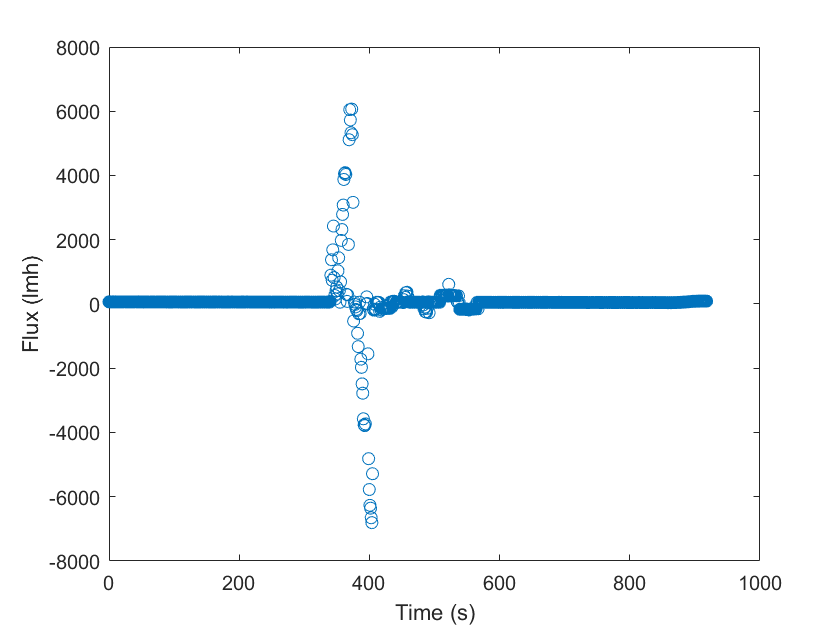

T1=table2array(T_table);

close all
time_s=T1(:,1);
mass_g=T1(:,5);
cond_mSpercm=T1(:,2);
sal_pct=cond_mSpercm/cond_at_1pct;%salinity in % by wt (where linear!)
n_av=t_min_av*60/t_interval;%number of points to make flux avg across

sal_pct_av=movmean(sal_pct,n_av);
flowrate_av=(mass_g(n_av+1:end)-mass_g(1:end-n_av))./(time_s(n_av+1:end)-time_s(1:end-n_av));
A_m=0.0238;%m^2 (SW measurement feed side, 2019 module)
flux_lmh=flowrate_av/1000*3600/A_m;

figure
plot(time_s(1:end-n_av),flux_lmh,'o')
xlabel('Time (s)')
ylabel('Flux (lmh)')

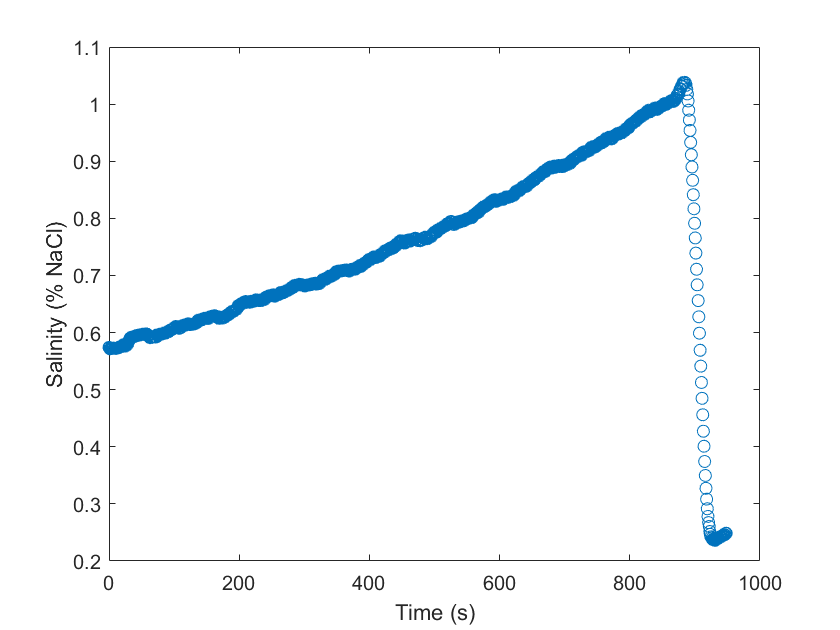


figure
plot(time_s,sal_pct_av,'o')
xlabel('Time (s)')
ylabel('Salinity (% NaCl)')

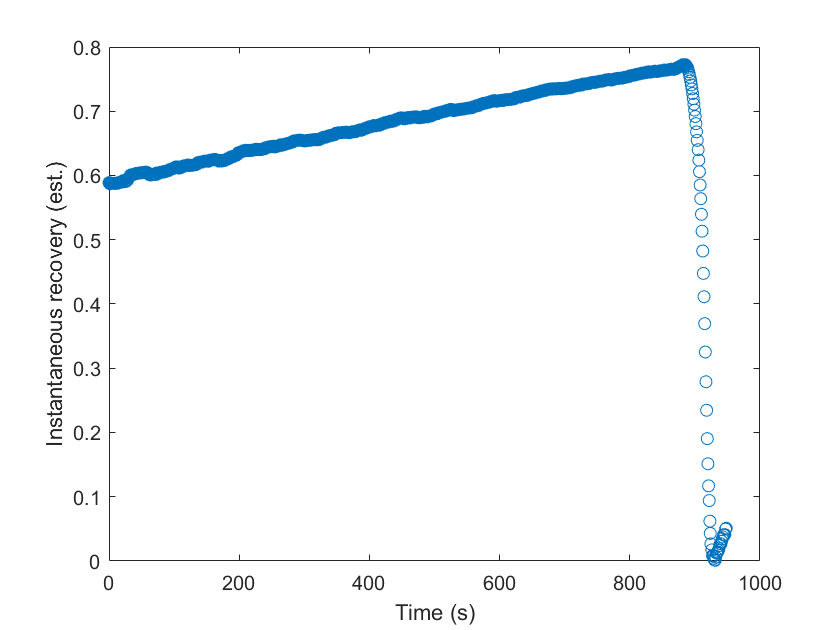


figure
RR_i_cond=1-sal_pct_i./sal_pct_av;%conductivity-based instantaneous RR assuming no salt permeation!
plot(time_s,RR_i_cond,'o')
xlabel('Time (s)')
ylabel('Instantaneous recovery (est.)')